close("all"); clear; clc;
setmadsympath();

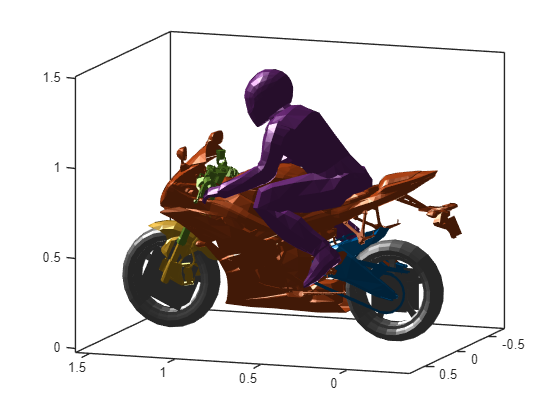

mblue = [0 0.4470 0.7410];
morange = [0.8500 0.3250 0.0980];
myellow = [0.9290 0.6940 0.1250];
mpurple = [0.4940 0.1840 0.5560];
mgreen = [0.4660 0.6740 0.1880];
mcyan = [0.3010 0.7450 0.9330];
mred = [0.6350 0.0780 0.1840];

fig = figure();
axe = axes(fig);
axis(axe,"equal");
box(axe,'on');
light(axe);
view(200,10);

dir = "./BigSportsSTL/";

ang = [0,0,0];
scale = [1,1,1];
coord = [0,0,300E-03];
ref = [1300E-03,525E-03,905E-03];
p = bikeSimAnimatorParameters(ang,scale,coord,ref);
base = MotoBody(dir + "base",p);
base.Patch.FaceColor = morange;
body = MotoBody(dir + "body",p);
body.Patch.FaceColor = morange;

ang = [0,0,0];
scale = [1,1,1];
coord = [1300E-03,0,-5E-03];
ref = [330E-03,283E-03,474E-03];
p = bikeSimAnimatorParameters(ang,scale,coord,ref);
swing_arm = MotoBody(dir + "swing_arm",p);
swing_arm.Patch.FaceColor = mblue;

ang = [0,0,0];
scale = [1,1,1];
coord = [30E-03,0,50E-03];
ref = [153E-03,548E-03,169E-03];
p = bikeSimAnimatorParameters(ang,scale,coord,ref);
handlebars = MotoBody(dir + "handlebars_no_arms",p);
handlebars.Patch.FaceColor = mgreen;

ang = [0,0,0];
scale = [1,1,1];
coord = [0,0,0];
ref = [512E-03,275E-03,585E-03];
p = bikeSimAnimatorParameters(ang,scale,coord,ref);
fork = MotoBody(dir + "fork",p);
fork.Patch.FaceColor = myellow;

ang = [0,1.5,0];
scale = [1,1,1];
coord = [0,0,-45E-03];
ref = [512E-03,275E-03,585E-03];
p = bikeSimAnimatorParameters(ang,scale,coord,ref);
front_fender = MotoBody(dir + "front_fender",p);
front_fender.Patch.FaceColor = myellow;

ang = [0,0,0];
scale = [1,1,1];
coord = [0,0,0];
ref = [512E-03,275E-03,650E-03];
p = bikeSimAnimatorParameters(ang,scale,coord,ref);
fork_top = MotoBody(dir + "fork_top",p);
fork_top.Patch.FaceColor = mgreen;

ang = [0,0,0];
scale = 0.95.*[1,1,1];
coord = [0,0,0];
ref = [0,0,0];
p = bikeSimAnimatorParameters(ang,scale,coord,ref);
rear_tire = MotoBody(dir + "rear_tire",p);

ang = [0,0,0];
scale = [1,1,1];
coord = [0,0,0];
ref = [0,0,0];
p = bikeSimAnimatorParameters(ang,scale,coord,ref);
front_tire = MotoBody(dir + "front_tire",p);

ang = [3,6,0];
scale = [1,1,1];
coord = [-20E-03,0,0];
ref = [500E-03,180E-03,500E-03];
p = bikeSimAnimatorParameters(ang,scale,coord,ref);
left_leg = MotoBody(dir + "driver_leg_left",p);
left_leg.Patch.FaceColor = mpurple;

ang = [-3,6,0];
scale = [1,1,1];
coord = [-20E-03,0,0];
ref = [500E-03,180E-03,500E-03];
p = bikeSimAnimatorParameters(ang,scale,coord,ref);
right_leg = MotoBody(dir + "driver_leg_right",p);
right_leg.Patch.FaceColor = mpurple;

ang = [0,0,0];
scale = [1,1,1];
coord = [-85E-03,0,-85E-03];
ref = [296E-03,404E-03,500E-03];
p = bikeSimAnimatorParameters(ang,scale,coord,ref);
driver = MotoBody(dir + "driver",p);
driver.Patch.FaceColor = mpurple;

ang = [0,0,0];
scale = [1.05,1,1];
coord = [-50E-03,0,10E-03];
ref = [484E-03,180E-03,180E-03];
p = bikeSimAnimatorParameters(ang,scale,coord,ref);
left_arm = MotoBody(dir + "left_arm",p);
left_arm.Patch.FaceColor = mpurple;

ang = [0,0,0];
scale = [1.05,1,1];
coord = [-50E-03,0,10E-03];
ref = [484E-03,180E-03,180E-03];
p = bikeSimAnimatorParameters(ang,scale,coord,ref);
right_arm = MotoBody(dir + "right_arm",p);
right_arm.Patch.FaceColor = mpurple;

yaw = 0;
camber = 0;
pitch = 0;
steer = 0;

tr = 70E-03;
rr = 290E-03 - tr;

f = @(R,d)rigidtform3d(R,d).A;

I = eye(3);
n0 = zeros(1,3);

Trt = f(rotz(yaw),n0)*f(I,[0,0,tr])*f(rotx(camber),n0)*f(I,[0,0,rr]);
rear_tire.setPose(Trt);

jounce = 10;
Tsa = Trt*f(roty(jounce).',n0)*f(roty(pitch),n0)*f(I,[100E-03,0,0]);
swing_arm.setPose(Tsa);

wb = 1300E-03;

Tsm = Trt*f(roty(pitch),n0)*f(I,[wb,0,-rr - tr]);
base.setPose(Tsm);
body.setPose(Tsm);

rf = 290E-03;
caster = 24;
rk = 26.5E-03;
Tfw = Tsm*f(I,[0,0,rf])*f(roty(caster).',n0)*f(I,[-rk,0,0]);
Tfw = Tfw*f(rotz(steer),n0)*f(I,[rk,0,0]);
front_tire.setPose(Tfw);

fork.setPose(Tfw);
front_fender.setPose(Tfw);

fl = 650E-03;
Tff = Tfw*f(I,[0,0,fl]);
fork_top.setPose(Tff);

Thb = Tff*f(I,[-30E-03,0,-40E-03]);
handlebars.setPose(Thb);

bl = 296E-03;
hl = 980E-03;
wl = 200E-03;
Tll = Trt*f(roty(pitch),n0)*f(I,[bl,wl,-rr - tr + hl]);
left_leg.setPose(Tll);

Trl = Trt*f(roty(pitch),n0)*f(I,[bl,-wl,-rr - tr + hl]);
right_leg.setPose(Trl);

hr = 570E-03;
Trd = Trt*f(roty(pitch),n0)*f(I,[500E-03,0,-rr - tr + hr]);
Trd = Trd*f(roty(45),n0)*f(I,[-296E-03,0,0]);
driver.setPose(Trd);

Tla = Trt*f(roty(pitch),n0)*f(I,[500E-03,290E-03,-rr - tr + hr]);
Tla = Tla*f(roty(45),n0)*f(I,[-300E-03,0,500E-03]);
left_arm.setPose(Tla);

Tra = Trt*f(roty(pitch),n0)*f(I,[500E-03,-290E-03,-rr - tr + hr]);
Tra = Tra*f(roty(45),n0)*f(I,[-300E-03,0,500E-03]);
right_arm.setPose(Tra);